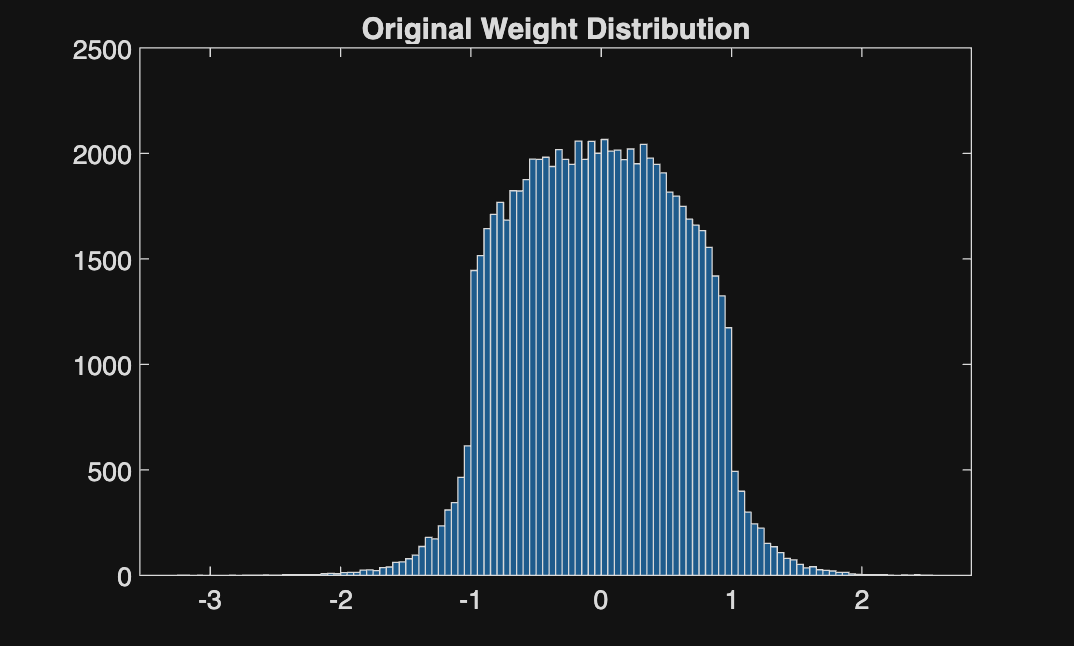

clc;
clear;

load('weightsAndBiases.mat','W1','b1','W2','b2');

images=loadMNISTImages('t10k-images');
labels=loadMNISTLabels('t10k-labels')';

Bx=2;
Bw=6;
W_frac=6;
ADC_bits=4;

ARRAY_ROWS=16;

slice_bits=1;
num_slices=Bw;

R=3;

%% Histogram sampling settings
sample_fraction=0.001;
allPartialMAC=[];

%% Initial Histograms

figure
histogram(W1)
title('Original Weight Distribution')

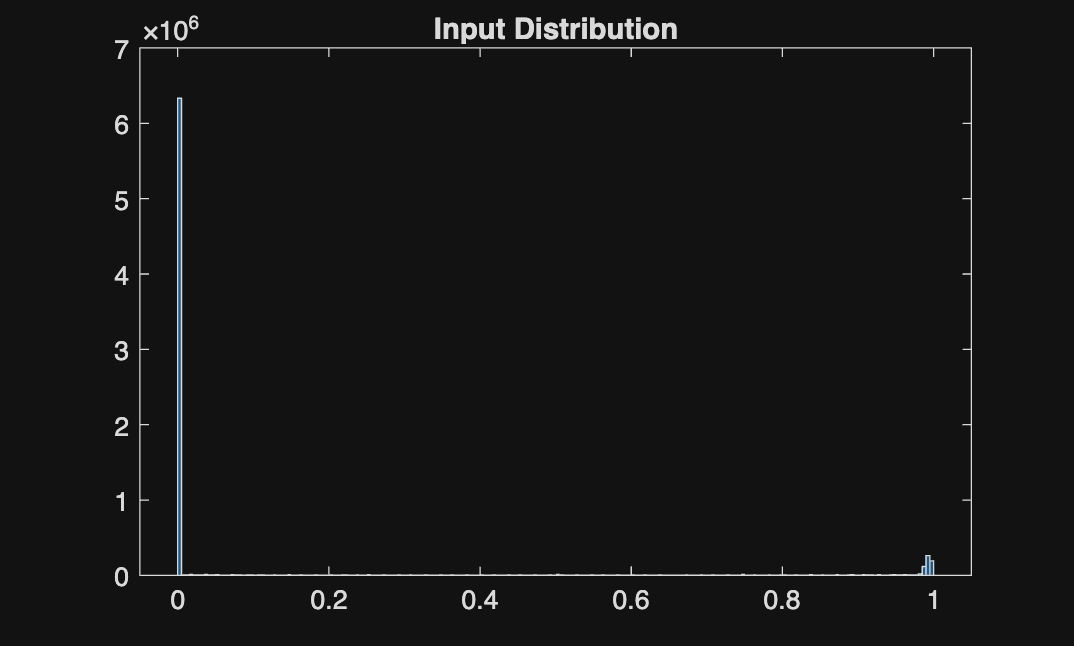


figure
histogram(images)
title('Input Distribution')

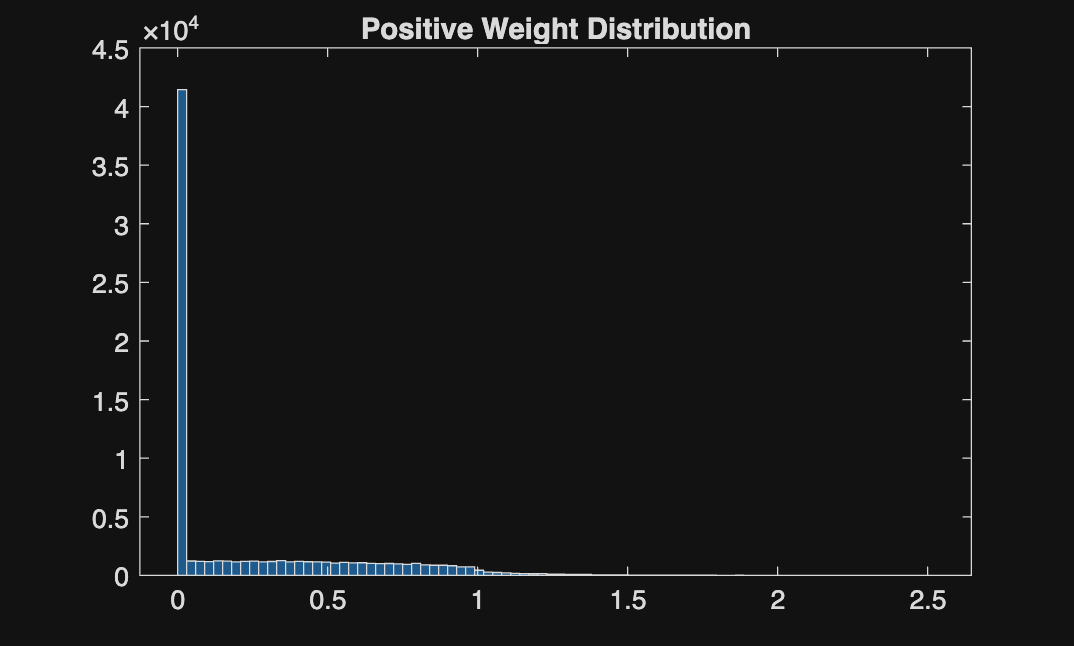


%% Positive / Negative weights

W1_pos=max(W1,0);
W1_neg=max(-W1,0);

figure
histogram(W1_pos)
title('Positive Weight Distribution')

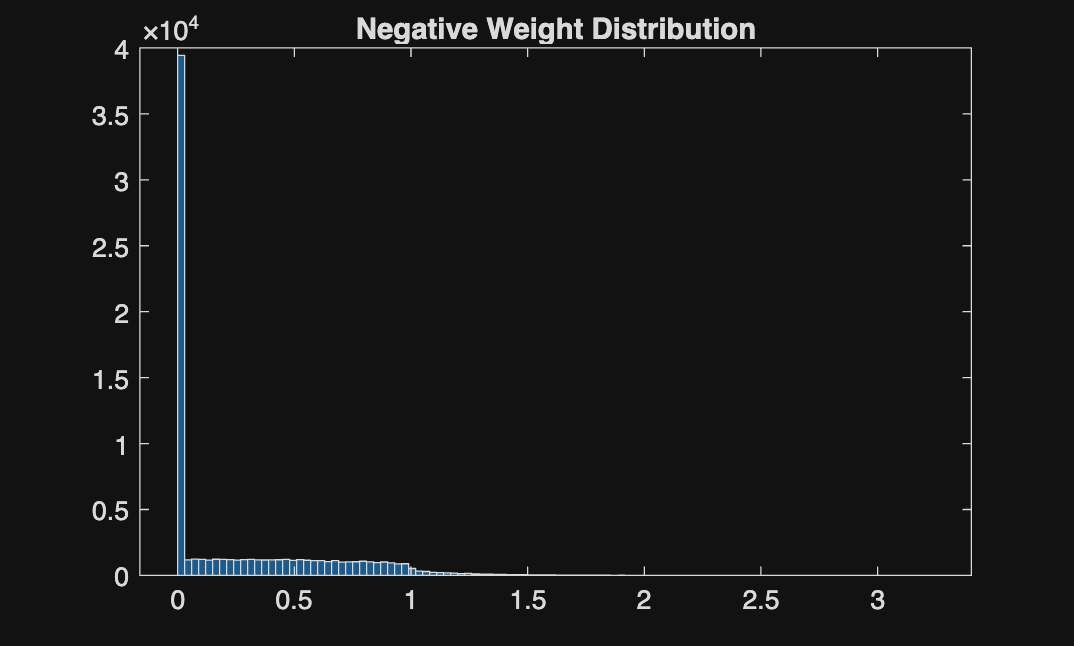


figure
histogram(W1_neg)
title('Negative Weight Distribution')

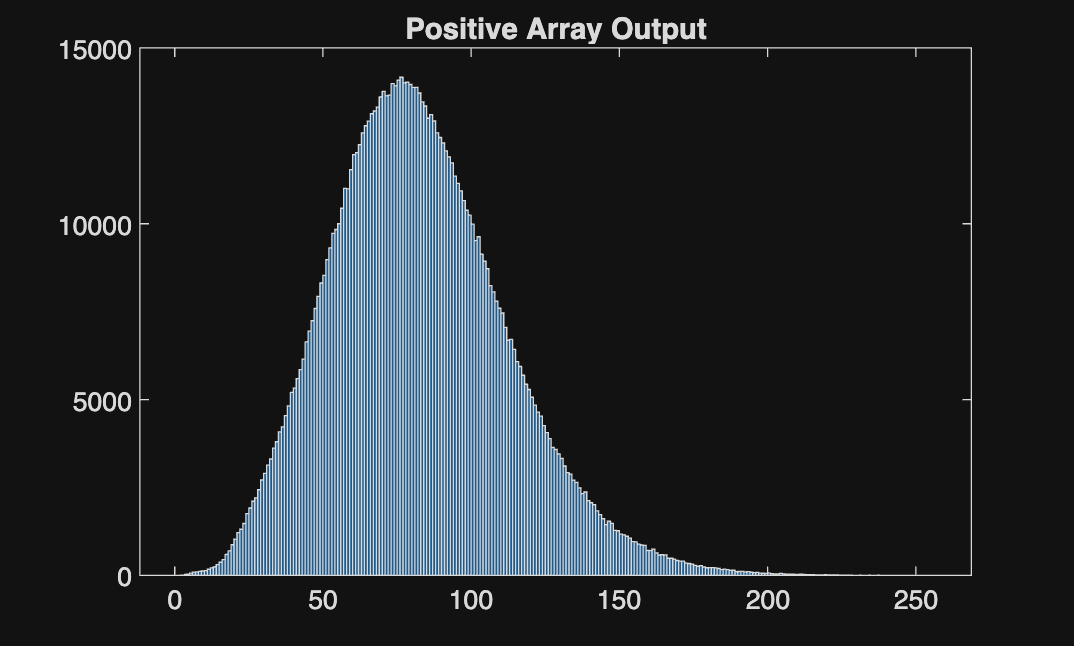


%% Quantization

W1_pos_Q=fi(W1_pos,0,Bw,W_frac);
W1_neg_Q=fi(W1_neg,0,Bw,W_frac);

images_Q=fi(images,0,Bx,Bx);

%% Integer representation

rawW_pos=int32(round(double(W1_pos_Q)*2^W_frac));
rawW_neg=int32(round(double(W1_neg_Q)*2^W_frac));

rawX=int32(round(double(images_Q)*2^Bx));

%% Input bitplanes

bitPlanesX=false(size(rawX,1),size(rawX,2),Bx);

for xb=1:Bx
    bitPlanesX(:,:,xb)=logical(bitget(rawX,xb));
end

%% ==================================================
%% POSITIVE ARRAY
%% ==================================================

z1_pos=zeros(size(W1,1),size(images,2));

for slice_idx=1:num_slices

    W_slice=logical(bitand(bitshift(rawW_pos,-(slice_idx-1)),1));

    slice_accumulator=zeros(size(W1,1),size(images,2));

    num_features=size(rawX,1);

    for start_idx=1:ARRAY_ROWS:num_features

        end_idx=min(start_idx+ARRAY_ROWS-1,num_features);

        W_tile=W_slice(:,start_idx:end_idx);

        for xb=1:Bx

            X_tile=bitPlanesX(start_idx:end_idx,:,xb);

            partialMAC=double(W_tile)*double(X_tile);

            partialMAC=partialMAC*2^(xb-1);

            active_rows=sum(W_tile,2);
            active_rows(active_rows==0)=1;

            partialMAC=partialMAC./active_rows;

            %% Save only sampled MAC values
            mask=rand(size(partialMAC))<sample_fraction;
            allPartialMAC=[allPartialMAC partialMAC(mask)'];

            %% ADC

            partialMAC=max(min(partialMAC,R),0);

            delta=R/(2^ADC_bits);

            partialMAC=round(partialMAC/delta)*delta;

            partialMAC=partialMAC.*active_rows;

            slice_accumulator=slice_accumulator+partialMAC;

        end
    end

    slice_scale=2^(slice_idx-1-W_frac);

    z1_pos=z1_pos+slice_accumulator*slice_scale;

end

%% ==================================================
%% NEGATIVE ARRAY
%% ==================================================

z1_neg=zeros(size(W1,1),size(images,2));

for slice_idx=1:num_slices

    W_slice=logical(bitand(bitshift(rawW_neg,-(slice_idx-1)),1));

    slice_accumulator=zeros(size(W1,1),size(images,2));

    num_features=size(rawX,1);

    for start_idx=1:ARRAY_ROWS:num_features

        end_idx=min(start_idx+ARRAY_ROWS-1,num_features);

        W_tile=W_slice(:,start_idx:end_idx);

        for xb=1:Bx

            X_tile=bitPlanesX(start_idx:end_idx,:,xb);

            partialMAC=double(W_tile)*double(X_tile);

            partialMAC=partialMAC*2^(xb-1);

            active_rows=sum(W_tile,2);
            active_rows(active_rows==0)=1;

            partialMAC=partialMAC./active_rows;

            %% Save only sampled MAC values
            mask=rand(size(partialMAC))<sample_fraction;
            allPartialMAC=[allPartialMAC partialMAC(mask)'];

            %% ADC

            partialMAC=max(min(partialMAC,R),0);

            delta=R/(2^ADC_bits);

            partialMAC=round(partialMAC/delta)*delta;

            partialMAC=partialMAC.*active_rows;

            slice_accumulator=slice_accumulator+partialMAC;

        end
    end

    slice_scale=2^(slice_idx-1-W_frac);

    z1_neg=z1_neg+slice_accumulator*slice_scale;

end

%% Reconstruction

z1_imc=z1_pos-z1_neg;

figure
histogram(z1_pos)
title('Positive Array Output')

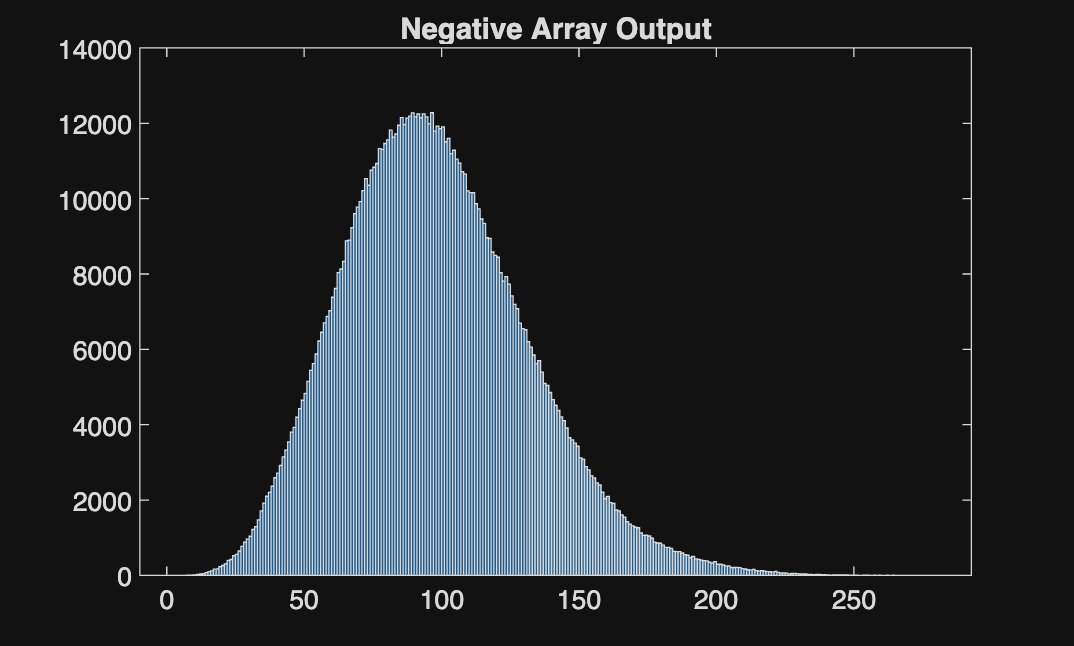


figure
histogram(z1_neg)
title('Negative Array Output')

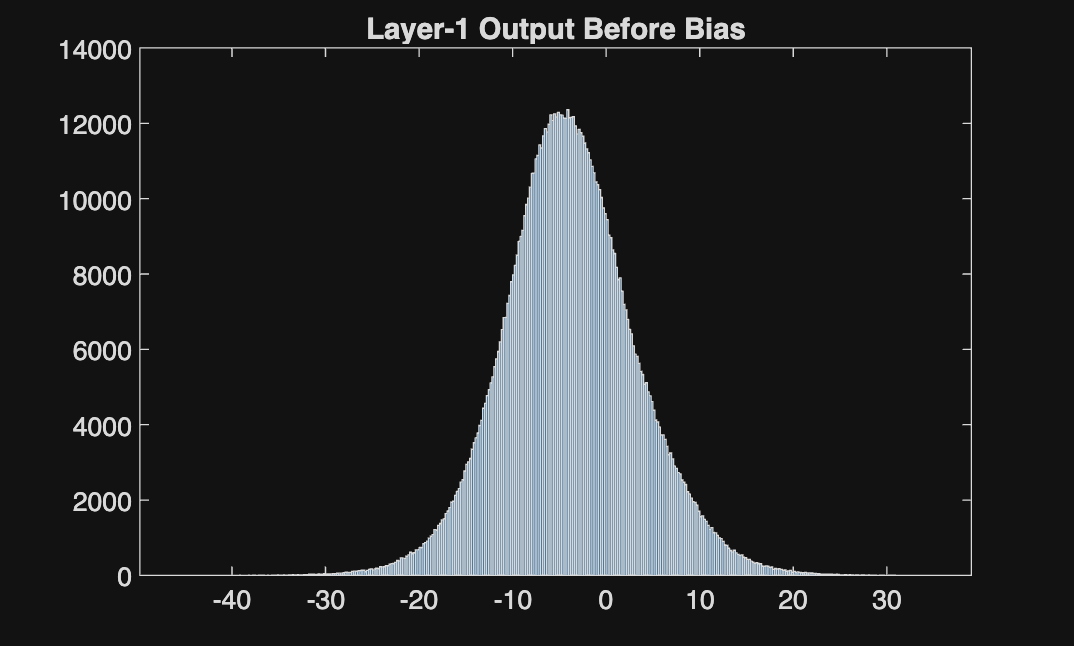


z1_imc=z1_imc/2^Bx;

figure
histogram(z1_imc)
title('Layer-1 Output Before Bias')


z1_imc=z1_imc+b1;

a1=max(0,z1_imc);

%% Layer 2

z2=W2*a1+b2;

[~,guesses]=max(z2,[],1);

guesses=guesses-1;

%% Accuracy

NumMatches=sum(labels==guesses);

Acc=NumMatches/numel(labels)*100;

fprintf('\n');
fprintf('Weight Precision     : %d bits\n',Bw);

Weight Precision     : 6 bits


fprintf('Activation Precision : %d bits\n',Bx);

Activation Precision : 2 bits


fprintf('ADC Precision        : %d bits\n',ADC_bits);

ADC Precision        : 4 bits


fprintf('Array Rows           : %d\n',ARRAY_ROWS);

Array Rows           : 16


fprintf('Slice Bits           : %d\n',slice_bits);

Slice Bits           : 1


fprintf('Accuracy             : %.2f %%\n',Acc);

Accuracy             : 95.85 %


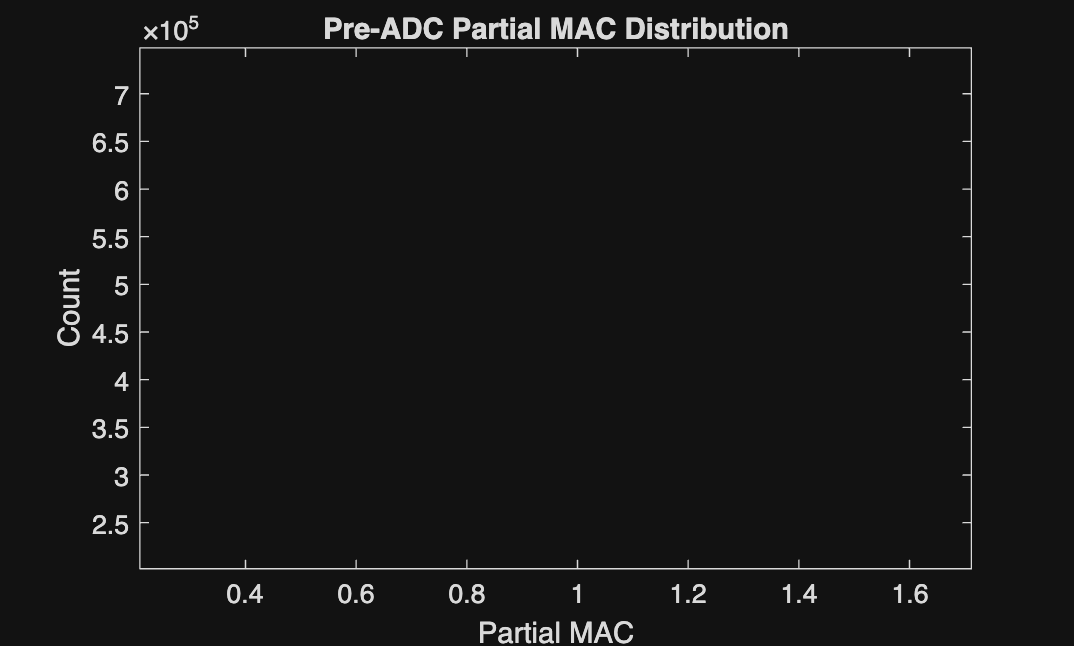


%% ==================================================
%% Partial MAC Histogram
%% ==================================================

figure
histogram(allPartialMAC,100)

xlabel('Partial MAC')
ylabel('Count')

title('Pre-ADC Partial MAC Distribution')


fprintf('\n');
fprintf('Sampled MAC values stored = %d\n',length(allPartialMAC));

Sampled MAC values stored = 1177527


fprintf('Max PartialMAC = %.4f\n',max(allPartialMAC));

Max PartialMAC = 2.0000


fprintf('Min PartialMAC = %.4f\n',min(allPartialMAC));

Min PartialMAC = 0.0000


fprintf('Mean PartialMAC = %.4f\n',mean(allPartialMAC));

Mean PartialMAC = 0.2183
